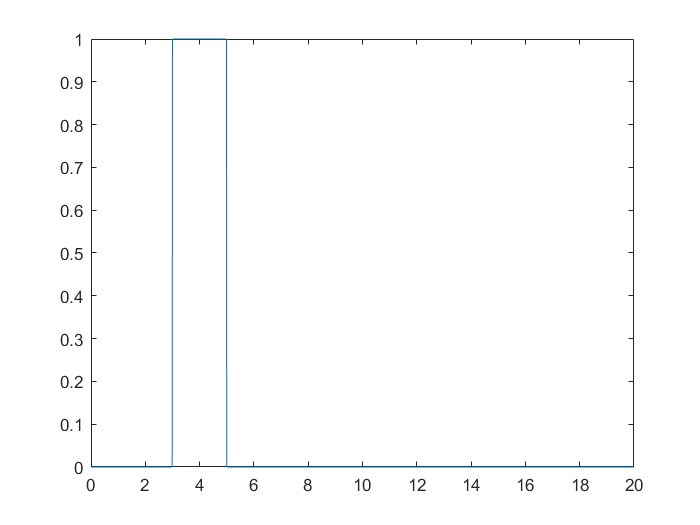

clc
clear
close all

t=0:0.01:20;
x=rect(t,3,5,1);
plot(t,x);

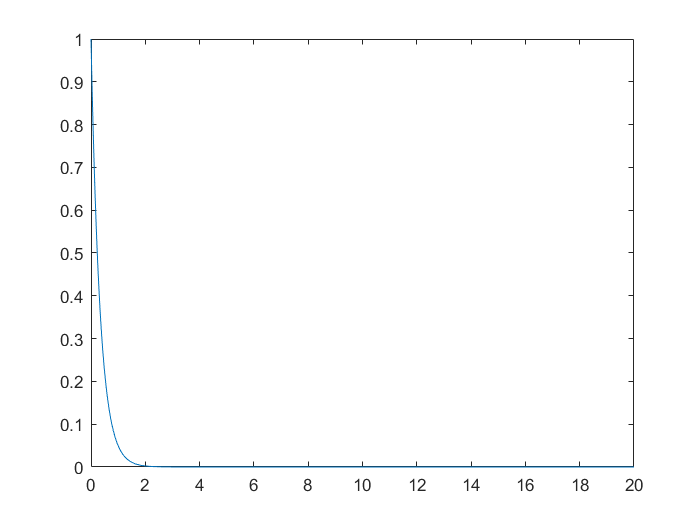

u=unit(t);
h=h5(t);
plot(t,h);

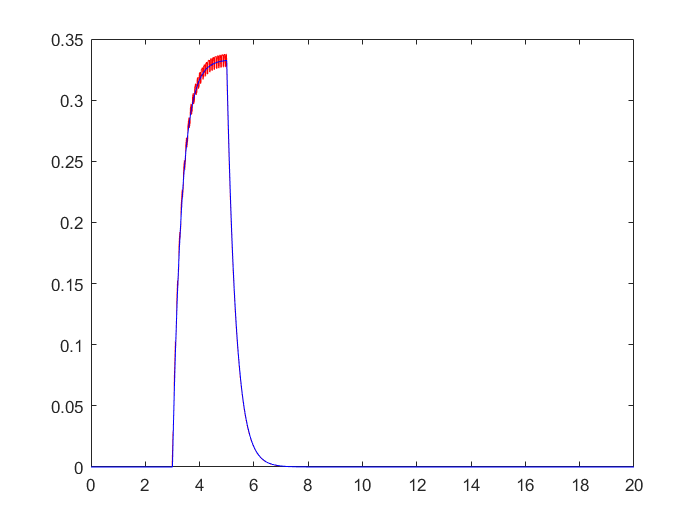

tau=-10:0.01:20;
h1=h5(tau);
x1=rect(tau,3,5,1);
for i=1:length(t)
    tt=t(i);
    h1_tt=h5(tt-tau);
    y_tt(i)=trapz(tau,x1.*h1_tt);
end 
plot(t,y_tt,"Color",'r');
hold on;
r=a5(t);
plot(t,r,"Color",'b');